# Labo C - synthese van digitale filters

#### 4.4 Pole-zero plaatsing

Effect van polen op de frequentiekarakteristiek?

    Polen trekken de frequentiekarakteristiek op bepaalde plaatsen omhoog, indien deze voorkomen                             in het nulpunt dan heeft de grafiek een standaard stijging van 20dB/dec.

Effect van nulpunten op frequentiekarakteristiek?

    Nulpunten trekken de grafien naar beneden, indien deze voorkomen in het nulpunt, dan zal de grafiek een standaard daling ven 20dB/dec hebben.

Wat is het effect van nulpunten op de eenheidscirkel op de frequentiekarakteristiek?

    Een nulpunt op de eenheidscirkel zorgt voor een daling naar 0 op die bepaalde frequentie.

Waar moeten de nulpunten liggen voor een laagdoorlaatfilter (LDL)?

    De nulpunten bij een LDL filter moeten aan de linkerkant van het pole-zero plot liggen.

Ontwerp nu een 2e orde recursief laagdoorlaatfilter dat een sample-interval gebruikt van 1ms, een poolresonantie heeft bij een centerfrequentie van 100Hz, en een bandbreedtevan 20Hz.  Gebruik daarbij de methode van de pole-zero plaatsing in hetz-vlak.  Een omwenteling op de eenheidscirkel komt overeen met een frequentiewijziging van 0 Hz tot de sample frequentie fs.  Het verband tussen de benodigde bandbreedte BW en destraalrvan  de  polen  kan  benaderd  worden  door r ≈ 1−(BW/fs)π(voorr >0.9).Voor de nulpunten worden twee transmissienulpunten gebruikt.

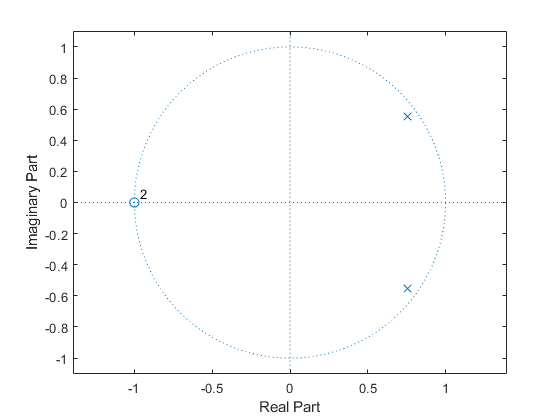

% sample interval 1ms
Ts = 1 * 10^-3;
fs = 1/Ts;
freq_c = 100;
poolHoek = deg2rad(fs/freq_c * 3.6);
nulHoek = deg2rad(180);
BW = 20;
r = 1 - (BW / fs) * pi;
polen = poly([r*exp(1i * poolHoek), r*exp(1i * -poolHoek) ]);
nullen = poly([1*exp(1i * nulHoek), 1*exp(1i * -nulHoek) ]);
zplane(nullen, polen);

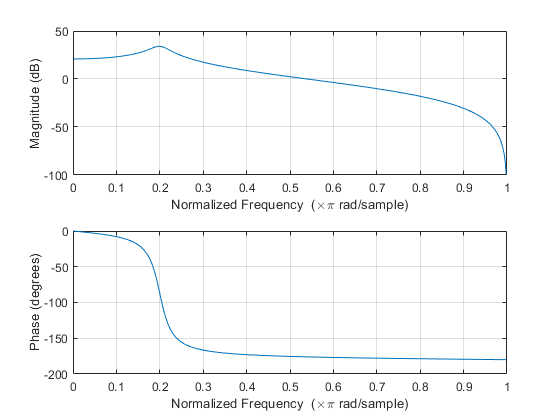

freqz(nullen, polen);

Bereken de co ̈effici ̈enten van de transferfunctie uit de ligging van de nulpunten en depolen.  Stel de transferfunctie en de differentievergelijking op.

H = tf(nullen, polen)

H =
 
                 
    s^2 + 2 s + 1
                 
  ------------------
                    
  s^2 - 1.516 s     
                    
            + 0.8783
                    
 
Continuous-time transfer function.



Differentievergelijking: $y\left(n+2\right)-1\ldotp 516y\left(n+1\right)+0\ldotp 8783=x\left(n+2\right)-1\ldotp 516x\left(n+1\right)+0\ldotp 8783$

Bereken de frequentieweergave bijf= 0,f=fs/4 enf=fs/2.

z = 1;
H0 = (z^2 + 2 * z + 1) / (z^2 - 1.516 * z + 0.8783)

H0 = 11.0406

z = 1i;
Hfs4 = (z^2 + 2 * z + 1) / (z^2 - 1.516 * z + 0.8783)

Hfs4 = -1.3108 - 0.1052i

z = -1;
Hfs2 = (z^2 + 2 * z + 1) / (z^2 - 1.516 * z + 0.8783)

Hfs2 = 0

Schrijf nu Matlab code om je berekeningen van de co ̈effici ̈enten grafisch te verifi ̈eren.Controleer ook de ligging van de polen en de frequentieresponsie.

zplane(nullen, polen);

% pool ligt op 36 graden
poolverh = 36 / 360;
poolfreq = poolverh * fs

poolfreq = 100

#### 4.5 Cauer filter en quantisatie

Ontwerp een 8e orde Cauer (of elliptisch) laagdoorlaatfilter met

Cut-off frequentie 300 Hz

fs = 4000;
Wp = 300/(fs/2);

Rimpel in de doorlaatband:  0.5 dB

Rp = 0.5;

Minimum sperbandattenuatie:  50 dB

Rs = 50;

Sample frequentie:  4 kHz

fs = 4000;

[b,a] = ellip(8, Rp, Rs, Wp)

b =     0.0046   -0.0249    0.0655   -0.1096    0.1289   -0.1096    0.0655   -0.0249    0.0046


a =     1.0000   -6.9350   21.5565  -39.1515   45.3885  -34.3667   16.5897   -4.6674    0.5860


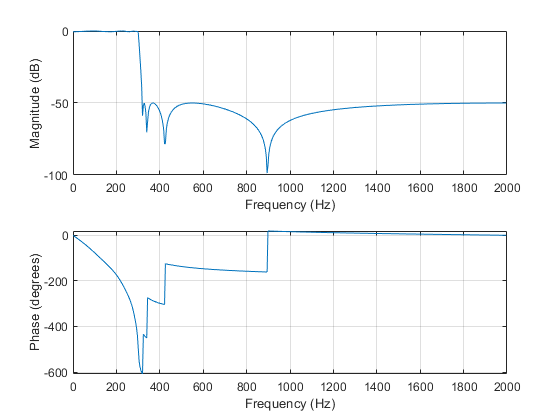

freqz(b,a,[],fs);

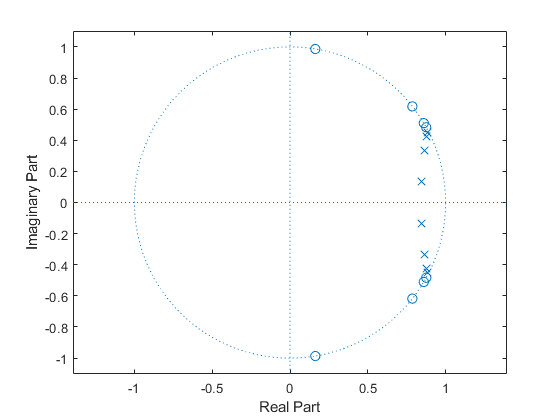

zplane(b, a);

Onderzoek de invloed van de co ̈effici ̈entnauwkeurigheid op de ligging van de polen en ze-ros en op de amplituderesponsie van het filter. Simuleer hiervoor een co ̈effici ̈entnauwkeurigheidvan 8 digits en 5 digits. Beeld hierbij de amplituderesponsie af. Vergelijk deze resultaten(zowel in z-vlak als in amplituderesponsie).  Zijn alle versies bruikbaar?

a8 = round(a, 8);
b8 = round(b, 8);
a5 = round(a, 5);
b5 = round(b, 5);
a,a5,a8,b,b5,b8

a =     1.0000   -6.9350   21.5565  -39.1515   45.3885  -34.3667   16.5897   -4.6674    0.5860


a5 =     1.0000   -6.9350   21.5565  -39.1515   45.3885  -34.3667   16.5897   -4.6674    0.5860


a8 =     1.0000   -6.9350   21.5565  -39.1515   45.3885  -34.3667   16.5897   -4.6674    0.5860


b =     0.0046   -0.0249    0.0655   -0.1096    0.1289   -0.1096    0.0655   -0.0249    0.0046


b5 =     0.0046   -0.0249    0.0655   -0.1096    0.1289   -0.1096    0.0655   -0.0249    0.0046


b8 =     0.0046   -0.0249    0.0655   -0.1096    0.1289   -0.1096    0.0655   -0.0249    0.0046


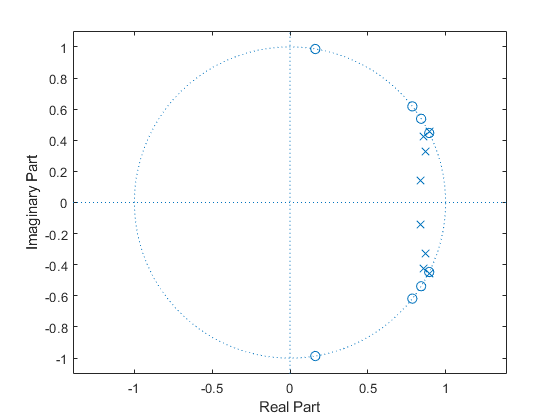

zplane(b5, a5);

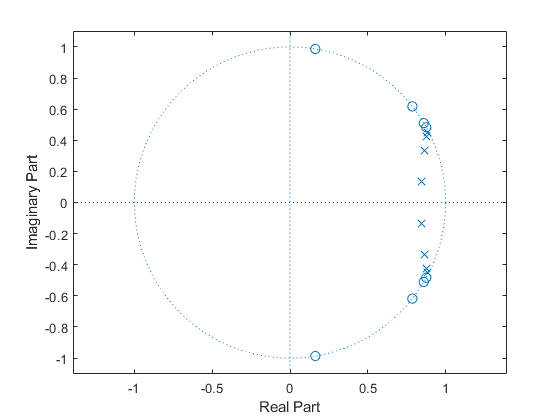

zplane(b8, a8);

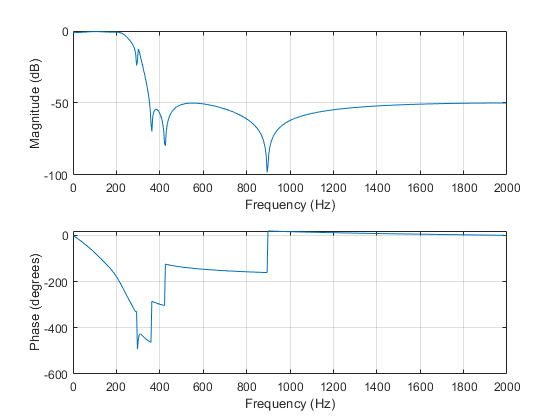

freqz(b5,a5,[],fs);

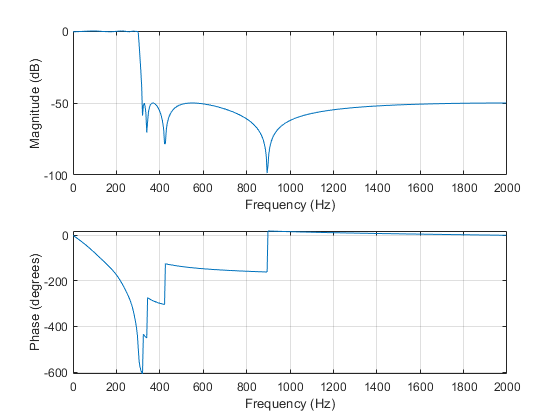

freqz(b8,a8,[],fs);

De coefficienten met 5 en 8 digits zijn bruikbaar maar voldoen niet meer aan onze opgegeven waarden.

Vul nu aan en bereken de polen van H(z) voor de twee nauwkeurigheidsbenaderingen.Wat besluit je hieruit?

We kunnen zien dat voor 8 digits het oke is maar bij 5 digits is het systeem onstabiel.

Vul aan en verifieer je vorig besluit met een onderzoek naar de impulsrespons bij deze verschillende co ̈effici ̈entnauwkeurigheden.

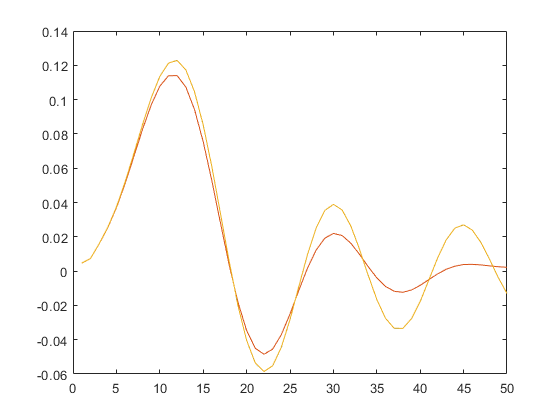

x = [1 zeros(1, 49)];
plot(filter(b,a,x));
hold on;
plot(filter(b5,a5,x));
hold on;
plot(filter(b8,a8,x));
hold off;

We zien duidelijk dat de fout op de impulsresponsie voor 8 digits niet te onderscheiden valt met de originele maar die van 5 digits is duidelijk anders.

Leg het verband m.b.t.  stabiliteit voor deze verschillende co ̈effici ̈entnauwkeurighedentussen alle analyses (z-vlak, amplituderesponsie, straal van de polen)

8 Digits:

    z-vlak: OK, alle polen en nulpunten binnen eenheidscirkel

    ampl-respons: OK, verschil met origineel is minimaal

    straal van polen: OK, ale polen vallen binnen eenheidscirkel

    stabiel

5 Digits:

    z-vlak: NOK, sommige polen valle buiten eenheidscirkel en zijn dus onstabiel

    ampl-respons: NOK, verschil met origineel te veel om aan specs te voldoen

    straal van polen: NOK, sommige polen vallen buiten eenheidscirkel

    onstabiel

#### 4.6 Realisatie met 2e orde trappen

[sos, g] = tf2sos(b, a);
H1 = tf([sos(1,1) sos(1,2) sos(1,3)], [sos(1,4) sos(1,5) sos(1,6)])

H1 =
 
                    
  s^2 - 0.3255 s + 1
                    
  ------------------
                    
  s^2 - 1.685 s     
                    
             + 0.729
                    
 
Continuous-time transfer function.



H2 = tf([sos(2,1) sos(2,2) sos(2,3)], [sos(2,4) sos(2,5) sos(2,6)])  

H2 =
 
                   
  s^2 - 1.573 s + 1
                   
  ------------------
                    
  s^2 - 1.725 s     
                    
            + 0.8573
                    
 
Continuous-time transfer function.



H3 = tf([sos(3,1) sos(3,2) sos(3,3)], [sos(3,4) sos(3,5) sos(3,6)])

H3 =
 
                   
   s^2 - 1.72 s + 1
                   
  ------------------
                    
  s^2 - 1.754 s     
                    
            + 0.9488
                    
 
Continuous-time transfer function.



H4 = tf([sos(4,1) sos(4,2) sos(4,3)], [sos(4,4) sos(4,5) sos(4,6)])

H4 =
 
                   
  s^2 - 1.751 s + 1
                   
  ------------------
                    
  s^2 - 1.771 s     
                    
            + 0.9882
                    
 
Continuous-time transfer function.



sos5 = round(sos, 5);
[a, b] = sos2tf(sos5, g)

a =     0.0046   -0.0249    0.0655   -0.1096    0.1289   -0.1096    0.0655   -0.0249    0.0046


b =     1.0000   -6.9350   21.5565  -39.1513   45.3882  -34.3664   16.5895   -4.6673    0.5860


1,2 van 4.6 done in sos

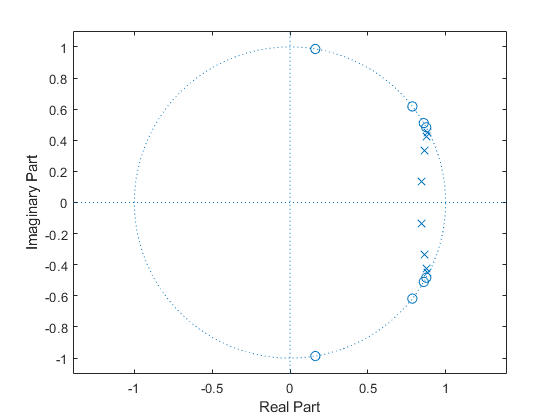

zplane(a, b);

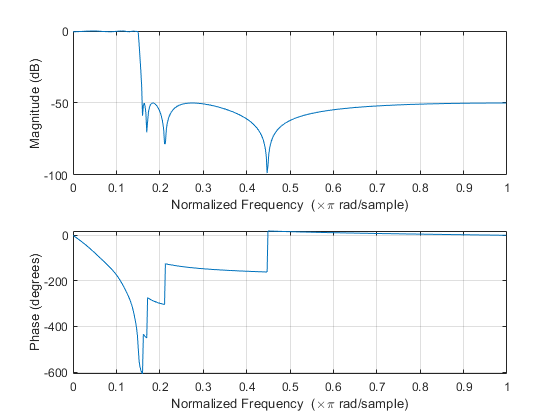

freqz(a, b);

sos2 = round(sos, 2)

sos2 =     1.0000   -0.3300    1.0000    1.0000   -1.6900    0.7300
    1.0000   -1.5700    1.0000    1.0000   -1.7200    0.8600
    1.0000   -1.7200    1.0000    1.0000   -1.7500    0.9500
    1.0000   -1.7500    1.0000    1.0000   -1.7700    0.9900


[a, b] = sos2tf(sos2, g)

a =     0.0046   -0.0249    0.0656   -0.1097    0.1291   -0.1097    0.0656   -0.0249    0.0046


b =     1.0000   -6.9300   21.5375  -39.1296   45.3983  -34.4156   16.6403   -4.6911    0.5904


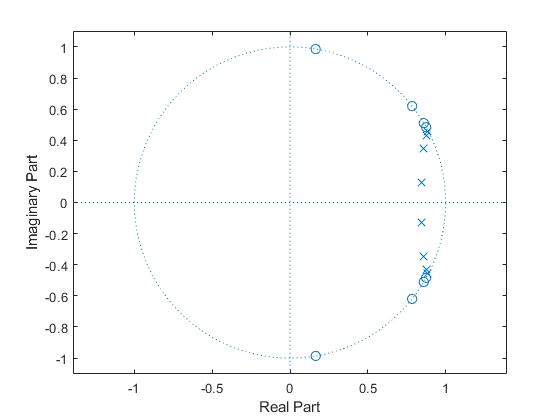

zplane(a, b);

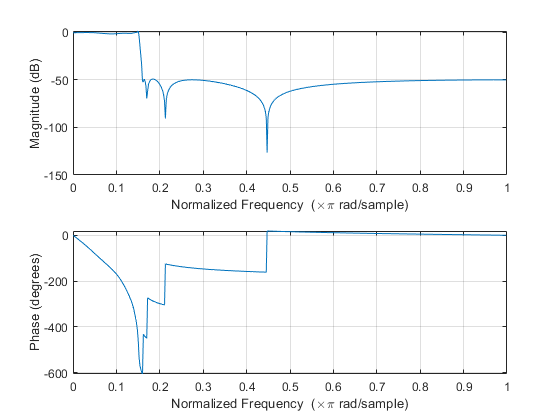

freqz(a, b);

#### 4.7 FIR-filter met lineaire fase

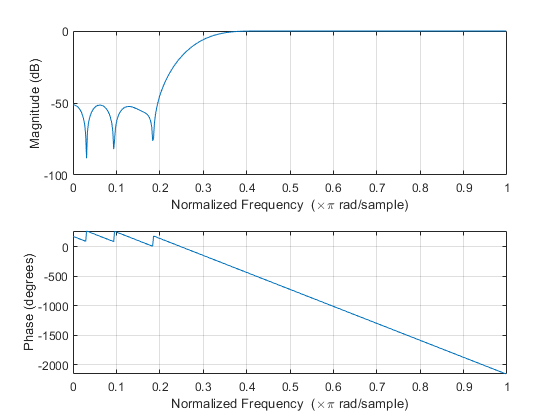

n = 32;
Fs = 1000;
Fc = 300;

bhi = fir1(n, Fc/Fs, 'high');
freqz(bhi, 1);

Het faseverloop is zoals gevraagd lineair maar zeer hoekig.

## Labo D

[x, Fs] = audioread("test(1).wav");
sound(x, Fs);

De toonhoogte verlaagt als de afspeelfrequentie verhoogt.

FIR filter bestaande uit 8000 nullen samples gelijk aan 1 op 1 en 0.9 op 2000.

sound(x, Fs*0.8);

sound(x, Fs*1.2);

fil = zeros([1, 8000]);
fil(1) = 1;
fil(2000) = 0.9;

sound(filter(fil, 1, x), Fs)

Dit creert een soort van echo in het begin en einde van het signaal.

IIR filter maken:

a = zeros([1, 2000]);
b = zeros([1, 2000]);
a(2000) = 1;
b(1) = 1;
b(2000) = -0.8;

sound(filter(a, b, x), Fs);

Nog steeds een soort van langere echo.

de all-pass reverberator

a = zeros([1, 2000]);
b = zeros([1, 2000]);
a(1) = -0.8;
a(2000) = -1;
b(1) = 1;
b(2000) = -0.2;

sound(filter(a, b, x), Fs);

Geen idee wat hier gebeurt.